# ROC

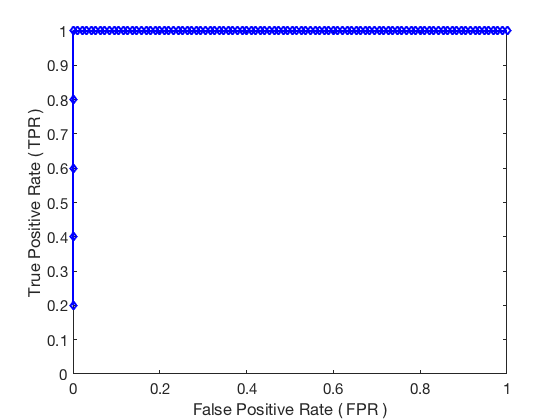

clearvars; close all; clc;

rng(1)


N = 1000; %number of sampled points to use
d = 100;

A = randn(N,d);

x = zeros(d,1);
x(randperm(d,5)) = randn(5,1);

% Add wighte gaussian noise to the function
f = A*x;

f = awgn(f,100);



B = pinv(A)*f;
[B,ix] = sort(abs(B));

x = x(ix);

for i=1:length(B)
    FP(i) = sum( and(~x,B) );
    TP(i) = sum( and( x,B) );
    B(i) = 0;
end

FPR = FP./sum(~x);
TPR = TP./sum(~~x);

plot(FPR,TPR,'-db','LineWidth',2)
axis([0 1 0 1])
ylabel('True Positive Rate ( TPR )')
xlabel('False Positive Rate ( FPR )')
set(gca,'FontSize',15)